# Lab 1 Submission

Name: Lilith Janevska

## Problem 1 Answer

Output:

det    Determinant.
    det(X) is the determinant of the square matrix X.
 
    Use COND instead of det to test for matrix singularity.
 
    See also cond.

    Documentation for det

## Problem 2 Answer

C = [1:20]
C2 = C .^ 2

Output:


  Columns 1 through 14

     1     4     9    16    25    36    49    64    81   100   121   144   169   196

  Columns 15 through 20

   225   256   289   324   361   400

## Problem 3 Answer

x = linspace(-pi,pi);
y1 = (x.*x).*sin(x);

figure
plot(x,y1)

Output:

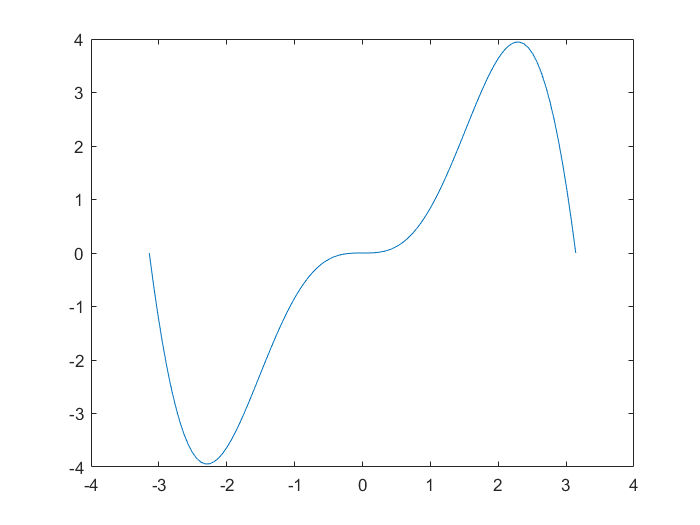

## Problem 4 Answer

function [result] = f(x)
    cumulative = 1
    for i = [1:x]
        cumulative = cumulative * i
    end
    result = cumulative;
end

Inputting x = 10:

ans =

     3628800

Which is the same as using the built-in factorial function

## Problem 5 Answer

MyBisectionMethod(-1,3,0.00001,@(x) (x^2)-7)
function [result] = MyBisectionMethod(a,b,tol,f)
arguments
    a double
    b double
    tol double
    f function_handle
end
    cs = [];
    accuracy = 999;
    while accuracy > tol
        midpoint = (b+a)/2;
        cs = [cs, midpoint];
        if f(a)*f(midpoint) < 0
            b = (a+b)/2;
        elseif f(a)*f(midpoint) > 0
            a = (a+b)/2;
        else
            break
        end
        accuracy = (b-a)/2;
    end
    result = cs;
end

When run for the specified range, function, and tolerence:

ans =

  Columns 1 through 10

    1.0000    2.0000    2.5000    2.7500    2.6250    2.6875    2.6562    2.6406    2.6484    2.6445

  Columns 11 through 18

    2.6465    2.6455    2.6460    2.6458    2.6456    2.6457    2.6457    2.6457

Which means it took 18 steps to get to the specified tolerence

This is exactly as was predicted, since -1+log2((b-a)/tol) = ~17.6, which implies 18 subdivisions of the interval